clear all
load fisheriris



[C,ia,ic] = unique(species);


data = [meas ic]

data =     5.1000    3.5000    1.4000    0.2000    1.0000
    4.9000    3.0000    1.4000    0.2000    1.0000
    4.7000    3.2000    1.3000    0.2000    1.0000
    4.6000    3.1000    1.5000    0.2000    1.0000
    5.0000    3.6000    1.4000    0.2000    1.0000
    5.4000    3.9000    1.7000    0.4000    1.0000
    4.6000    3.4000    1.4000    0.3000    1.0000
    5.0000    3.4000    1.5000    0.2000    1.0000
    4.4000    2.9000    1.4000    0.2000    1.0000
    4.9000    3.1000    1.5000    0.1000    1.0000


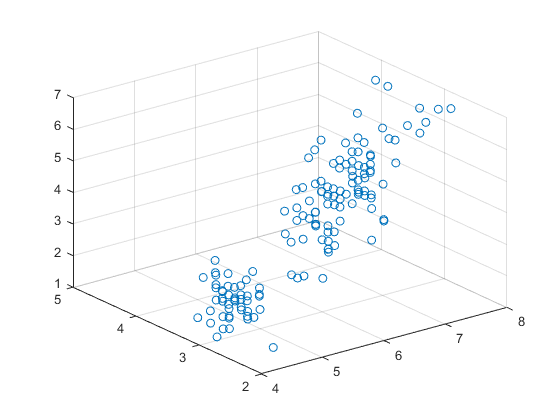


scatter3(meas(:,1), meas(:,2), meas(:,3))

polynomial normal



input = normc(meas(51:150,:))

input =     0.1112    0.1107    0.0945    0.0810
    0.1016    0.1107    0.0905    0.0868
    0.1096    0.1072    0.0985    0.0868
    0.0873    0.0796    0.0804    0.0752
    0.1032    0.0969    0.0925    0.0868
    0.0905    0.0969    0.0905    0.0752
    0.1001    0.1141    0.0945    0.0926
    0.0778    0.0830    0.0663    0.0579
    0.1048    0.1003    0.0925    0.0752
    0.0826    0.0934    0.0784    0.0810


% output = 2*(ic(51:150,:))-5
output = (ic(51:150,:))

output =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


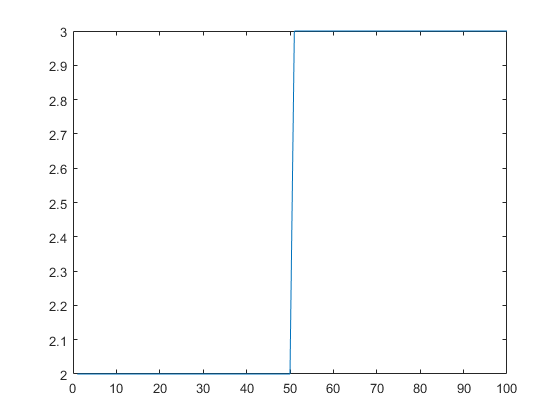



plot(output)


ex= 0:10

ex =      0     1     2     3     4     5     6     7     8     9    10


tic
w = pinv([input(:,1).^[0:3] input(:,2).^[1:3] input(:,3).^[1:3] input(:,4).^[1:3]])*output;
toc

Elapsed time is 0.004685 seconds.


y = [input(:,1).^[0:3] input(:,2).^[1:3] input(:,3).^[1:3] input(:,4).^[1:3]]*w

y =     1.9507
    2.0202
    2.1805
    2.0357
    2.1870
    2.1143
    2.2107
    2.1065
    1.9950
    2.0569


classif = y>0

classif = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


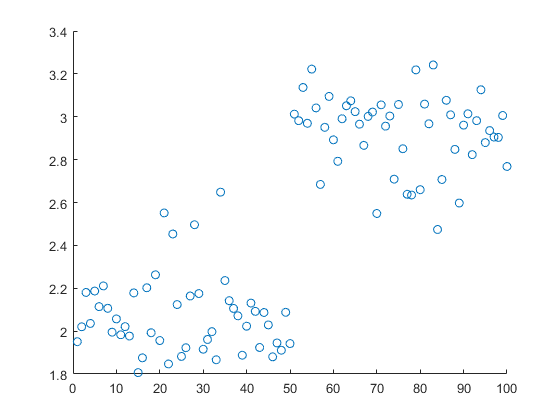


[B1,I] = sort(output);
B2 = output(I);

scatter(1:100,y)

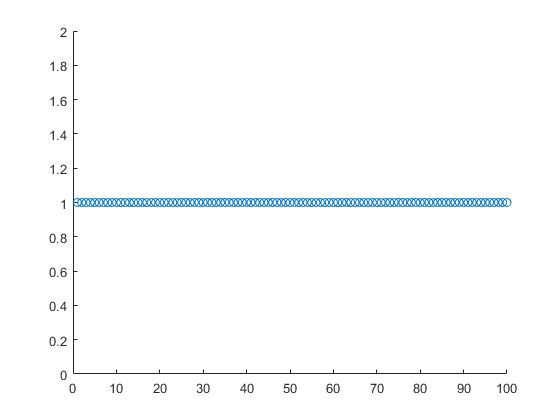

scatter(1:100,classif)

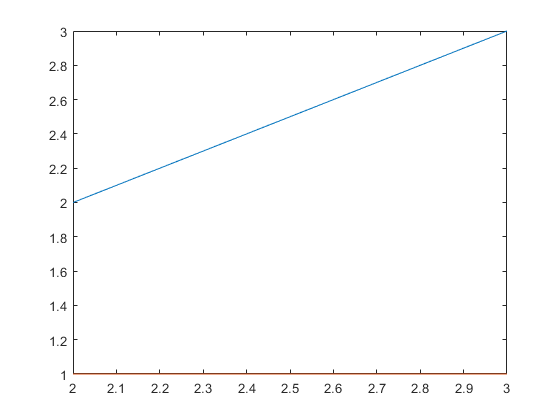


plot([B1 B1],[B2 classif(I)])


rataa = norm(y-output)/norm(output)

rataa = 0.0745

polynomial cross


batchsize=75

batchsize = 75

indexes= randperm(100);

measis = normc(meas(1:100,:))

measis =     0.0926    0.1116    0.0437    0.0207
    0.0890    0.0957    0.0437    0.0207
    0.0853    0.1021    0.0406    0.0207
    0.0835    0.0989    0.0468    0.0207
    0.0908    0.1148    0.0437    0.0207
    0.0980    0.1244    0.0531    0.0414
    0.0835    0.1084    0.0437    0.0310
    0.0908    0.1084    0.0468    0.0207
    0.0799    0.0925    0.0437    0.0207
    0.0890    0.0989    0.0468    0.0103


input = (measis(indexes(1:75),:))

input =     0.0926    0.1212    0.0499    0.0207
    0.0799    0.0957    0.0406    0.0207
    0.0871    0.0957    0.0437    0.0103
    0.0835    0.0989    0.0468    0.0207
    0.0835    0.1148    0.0312    0.0207
    0.1035    0.0893    0.1405    0.1345
    0.1216    0.0989    0.1373    0.1449
    0.0853    0.1021    0.0499    0.0207
    0.1271    0.1021    0.1467    0.1449
    0.1107    0.0893    0.1467    0.1242


output =  (ic(indexes(1:75)))-1

output =      0
     0
     0
     0
     0
     1
     1
     0
     1
     1



testinput = (measis(indexes(76:100),:))

testinput =     0.1216    0.0957    0.1561    0.1759
    0.0999    0.0765    0.1155    0.1035
    0.0908    0.1084    0.0499    0.0414
    0.1053    0.0861    0.1280    0.1035
    0.1107    0.0957    0.1436    0.1449
    0.0926    0.1212    0.0468    0.0310
    0.1144    0.1052    0.1467    0.1656
    0.1216    0.0989    0.1467    0.1552
    0.0926    0.1084    0.0468    0.0207
    0.1089    0.1084    0.1405    0.1656


testoutput = (ic(indexes(76:100)))-1

testoutput =      1
     1
     0
     1
     1
     0
     1
     1
     0
     1



n =4

n = 4


B=[]


B =

     []



for i = 1:batchsize
f= outproduct(input(i,1).^[0:n],input(i,2).^[0:n],input(i,3).^[0:n], input(i,4).^[0:n]);
B(i,:)=f(:)';
end

w = pinv(B)*output;

y = B*w

y =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.0000
    1.0000
    0.0000
    1.0000
    1.0000


classif = y>0

classif = 75×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


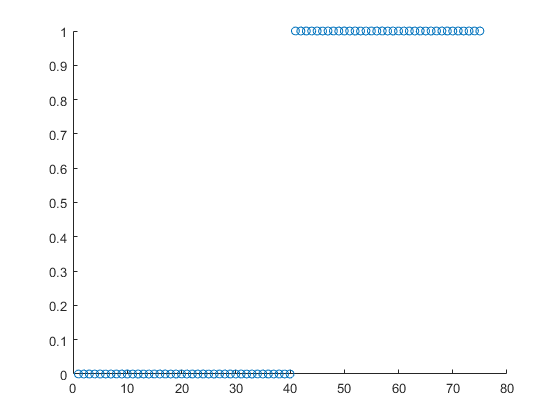

zet=[];
zet(indexes(1:batchsize))=y;
zet(zet==0) = [];
scatter(1:batchsize,zet)

hold on 
plot(0.5)
hold off

% scatter(1:batchsize,sort(classif))


% TEST set

Btest=[]


Btest =

     []



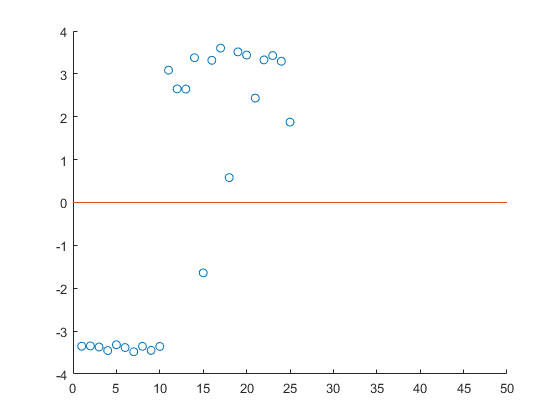

for i = 1:25
f= outproduct(testinput(i,1).^[0:n],testinput(i,2).^[0:n],testinput(i,3).^[0:n], testinput(i,4).^[0:n]);
Btest(i,:)=f(:)';
end

y = Btest*w;

zet=[];
zet(indexes(76:100))=y;
zet(zet==0) = [];
scatter(1:25,zet)
hold on 
plot([0 50], [0.0 0.0])
hold off



% rataa = norm(y-output)/norm(output)

training logistic sigmoid


alpha=1

alpha = 1


for i= 1:100

z1 = B*w;
a1 = (1+exp(-z1)).^-1;
d1= a1.*(1-a1).*(a1-output);

w = pinv(B)*(z1-alpha*d1);
end

zy = B*w;
ay = (1+exp(-zy)).^-1;

classif = ay>0.5

classif = 75×1 logical array
   0
   0
   0
   0
   0
   1
   1
   0
   1
   1


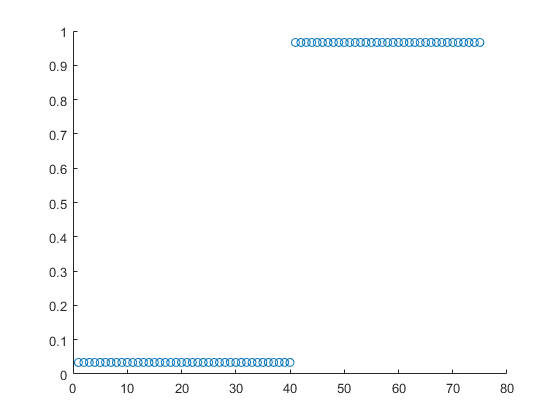

zet=[];
zet(indexes(1:batchsize))=ay;
zet(zet==0) = [];
scatter(1:batchsize,zet)

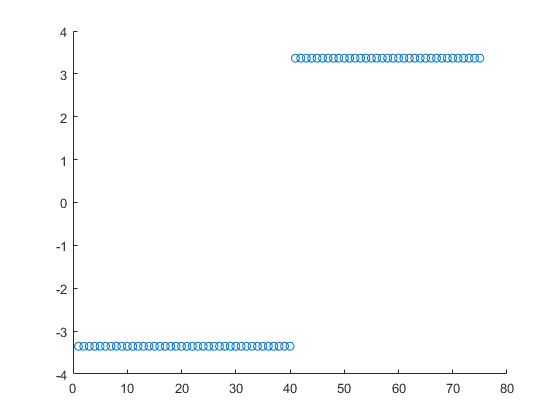


zet=[];
zet(indexes(1:batchsize))=zy;
zet(zet==0) = [];
scatter(1:batchsize,zet)